# Extraction of the Lookup Table

Configuration

root = 'C:/Users/maely/OneDrive/Bureau/ENSTA/CESURE/AMBER/monte-carlo-simulation-sphere-PGSE-main/data';  
projname = 'AMBER_maelyne';
population_type = 'lognorm';
population_label = [population_type, '_population_RealisticTests2_V3'];
projectpath = fullfile(root, projname, population_label);

lut_file = fullfile(projectpath, 'lookup_table_val.mat');

if isfile(lut_file)
    fprintf('Loading existing lookup table...\n');
    load(lut_file, 'params', 'signals_4D', 'sequence');
else
    fprintf('Lookup table not found. Running generation...\n');
    params_file = fullfile(projectpath, 'params_in.txt');

    if exist(params_file, 'file')
        params_data = readmatrix(params_file);
        Ncombos = size(params_data, 1);
    else
        error('params_in.txt not found in %s', projectpath);
    end

    simdir_ref = fullfile(projectpath, 'sphere_0001');

    % -------------------------------------------------------------------------
    % Load b-table avec doublons (15 b-values × 64 directions)
    % -------------------------------------------------------------------------
    btab_raw = readmatrix(fullfile(simdir_ref, 'gradient_bvalstab.txt'));
    % btab_raw contient n_bval_all * n_bvec valeurs (ex: 15*64 = 960 lignes)

    Btab = readmatrix(fullfile(simdir_ref, 'gradient_btab.txt'));
    % Btab est un vecteur de taille 4 * n_bval_all * n_bvec
    % reshape en matrice 4 × (n_bval_all * n_bvec)
    btab = reshape(Btab, 4, []);  % [4 × 960]
    % NE PAS supprimer de colonnes ici (btab(:, 641:768)=[] était un mauvais fix)

    % Déduire n_bvec : nombre de directions consécutives pour la première b-value
    bval_col = btab(1, :);  % première ligne = b-values
    first_bval = bval_col(1);
    n_bvec = sum(abs(bval_col - first_bval) < 1e-6);  % nb de directions par b-value = 64

    % b-values dans l'ordre (une par bloc de n_bvec directions)
    bval_all = bval_col(1:n_bvec:end)';        % [15 × 1], avec doublons, en ms/um^2
    n_bval_all = numel(bval_all);               % 15

    % b-values uniques pour la LUT finale
    bval_unique = unique(bval_all);             % [13 × 1]
    n_bval_unique = numel(bval_unique);         % 13

    % Directions de gradient (depuis le premier bloc de n_bvec directions)
    bvecs = btab(2:end, 1:n_bvec)';            % [64 × 3]

    % -------------------------------------------------------------------------
    % Diffusion times et pulse widths
    % -------------------------------------------------------------------------
    TD = readmatrix(fullfile(simdir_ref, 'TD_array.txt'));
    n_del = numel(TD);  % 2

    pulse_widths = readmatrix(fullfile(simdir_ref, 'gradient_DELdel.txt'));
    pulse_widths = reshape(pulse_widths, 2, []).';
    delta = pulse_widths(1:n_del, 2);

    % -------------------------------------------------------------------------
    % Vérification de la taille attendue des signaux
    % sig_diffusion.txt : n_bvec * n_bval_all * n_del = 64 * 15 * 2 = 1920
    % -------------------------------------------------------------------------
    n_signals_expected = n_bvec * n_bval_all * n_del;
    fprintf('Expected signal length per simulation: %d\n', n_signals_expected);
    fprintf('  (n_bvec=%d × n_bval_all=%d × n_del=%d)\n', n_bvec, n_bval_all, n_del);
    fprintf('After merging duplicates: n_bval_unique=%d\n\n', n_bval_unique);

    % -------------------------------------------------------------------------
    % Sequence struct (LUT utilise les b-values uniques)
    % -------------------------------------------------------------------------
    sequence.bval       = bval_unique;      % [13 × 1], valeurs uniques
    sequence.bval_all   = bval_all;         % [15 × 1], avec doublons (pour debug)
    sequence.bvecs      = bvecs;            % [64 × 3]
    sequence.n_bval     = n_bval_unique;    % 13
    sequence.n_bval_all = n_bval_all;       % 15
    sequence.n_bvec     = n_bvec;           % 64
    sequence.n_del      = n_del;            % 2
    sequence.TD         = TD;
    sequence.delta      = delta;

    % -------------------------------------------------------------------------
    % Outputs
    % -------------------------------------------------------------------------
    params     = zeros(Ncombos, 4);                            % [f, Dex, rmean, rsd]
    signals_4D = zeros(Ncombos, n_del, n_bval_unique, n_bvec); % [N × d × b × v]

    % -------------------------------------------------------------------------
    % Boucle sur les simulations
    % -------------------------------------------------------------------------
    for i = 1:Ncombos
        simname = sprintf('sphere_%04d', i);
        simdir  = fullfile(projectpath, simname);

        % --- Paramètres de simulation ---
        parafile = fullfile(simdir, 'sim_para.txt');
        if ~exist(parafile, 'file')
            warning('Missing sim_para.txt for simulation %d', i);
            continue;
        end
        paravalues = readmatrix(parafile);
        Dex   = paravalues(5);

        % --- Paramètres de population ---
        pop_para_file = fullfile(simdir, 'population_para.txt');
        if ~exist(pop_para_file, 'file')
            warning('Missing population_para.txt for simulation %d', i);
            continue;
        end
        pop_para = readmatrix(pop_para_file);
        rmean = pop_para(1);
        rsd   = pop_para(2);
        f     = pop_para(4);

        params(i, :) = [f, Dex, rmean, rsd];

        % --- Chargement des signaux bruts ---
        sigfile = fullfile(simdir, 'sig_diffusion.txt');
        if ~exist(sigfile, 'file')
            warning('Missing sig_diffusion.txt for simulation %d', i);
            continue;
        end
        sig = readmatrix(sigfile);

        if numel(sig) ~= n_signals_expected
            warning('Simulation %d: expected %d signals, got %d. Skipping.', ...
                i, n_signals_expected, numel(sig));
            continue;
        end

        % Valeurs négatives ou nulles → remplacer par un plancher
        NPar = paravalues(3);
        sig  = sig / NPar;          % normalisation
        sig(sig < 1e-6) = 1e-6;     % plancher après normalisation (inchangé)

        % --- Reshape : [n_bvec × n_bval_all × n_del] ---
        % L'ordre de stockage CUDA est : bvec varie en premier, puis bval, puis TD
        sig3D = reshape(sig, [n_bvec, n_bval_all, n_del]);
        sig3D = permute(sig3D, [3, 2, 1]);  % → [n_del × n_bval_all × n_bvec]

        % --- Moyenne des b-values dupliquées → [n_del × n_bval_unique × n_bvec] ---
        sig3D_unique = zeros(n_del, n_bval_unique, n_bvec);
        for b = 1:n_bval_unique
            idx = abs(bval_all - bval_unique(b)) < 1e-6;  % localise les doublons
            if sum(idx) > 1
                fprintf('  Simulation %d: averaging %d occurrences of bval=%.3f\n', ...
                    i, sum(idx), bval_unique(b));
            end
            sig3D_unique(:, b, :) = mean(sig3D(:, idx, :), 2);
        end

        signals_4D(i, :, :, :) = sig3D_unique;

        if mod(i, 100) == 0
            fprintf('Processed %d / %d simulations...\n', i, Ncombos);
        end
    end

    % -------------------------------------------------------------------------
    % Sauvegarde
    % -------------------------------------------------------------------------
    save(fullfile(projectpath, 'lookup_table_val.mat'), ...
        'params', 'signals_4D', 'sequence', '-v7.3');
    disp('Lookup table saved successfully.');
end

Loading existing lookup table...


# Checking LUT generation

%% =========================================================
%% VERIFICATION DE LA LOOKUP TABLE
%% =========================================================

%% 1. Vérification structurelle de base
disp('=== Structure de la LUT ===');

=== Structure de la LUT ===


fprintf('Taille signals_4D : [%d × %d × %d × %d]\n', size(signals_4D));

Taille signals_4D : [1090 × 2 × 13 × 64]


fprintf('  → [Ncombos=%d, n_del=%d, n_bval=%d, n_bvec=%d]\n', ...
    size(signals_4D,1), size(signals_4D,2), size(signals_4D,3), size(signals_4D,4));

  → [Ncombos=1090, n_del=2, n_bval=13, n_bvec=64]


fprintf('Nombre de paramètres : %d combos × %d params\n', size(params,1), size(params,2));

Nombre de paramètres : 1090 combos × 4 params



disp('--- b-values (ms/µm²) ---');

--- b-values (ms/µm²) ---


disp(sequence.bval');

    0.1000    0.2000    0.5000    0.7000    1.3000    1.4000    2.6000    3.8000    4.2000    6.0000    7.3000   12.0000   17.8000



fprintf('  → %d valeurs uniques (attendu : 13)\n', sequence.n_bval);

  → 13 valeurs uniques (attendu : 13)



disp('--- Diffusion times (ms) ---');

--- Diffusion times (ms) ---


disp(sequence.TD');

    19    49



fprintf('  → %d temps (attendu : 2)\n', sequence.n_del);

  → 2 temps (attendu : 2)



fprintf('--- Directions de gradient : %d (attendu : 64) ---\n', sequence.n_bvec);

--- Directions de gradient : 64 (attendu : 64) ---



%% 2. Vérification des valeurs aberrantes
fprintf('\n=== Santé des signaux ===\n');


=== Santé des signaux ===


fprintf('Min signal : %.6f\n', min(signals_4D(:)));

Min signal : 0.000001


fprintf('Max signal : %.6f\n', max(signals_4D(:)));

Max signal : 0.934346


fprintf('NaN count  : %d\n',   sum(isnan(signals_4D(:))));

NaN count  : 0


fprintf('Inf count  : %d\n',   sum(isinf(signals_4D(:))));

Inf count  : 0


fprintf('Zeros count: %d\n',   sum(signals_4D(:) == 0));

Zeros count: 0



fprintf('Valeurs au plancher (<=1e-6) : %d / %d (%.3f%%)\n', ...
    sum(signals_4D(:) <= 1e-6), ...
    numel(signals_4D(:)), ...
    100*mean(signals_4D(:) <= 1e-6));

Valeurs au plancher (<=1e-6) : 64325 / 1813760 (3.547%)



% Quelles simulations sont concernées ?
[sim_idx, ~, ~, ~] = ind2sub(size(signals_4D), find(signals_4D(:) <= 1e-6));
fprintf('Simulations concernées : %d uniques\n', numel(unique(sim_idx)));

Simulations concernées : 847 uniques


disp(unique(sim_idx)');

  Columns 1 through 833

           7           8           9          10          11          12          13          15          16          17          18          19          20          21          22          23          24          25          26          28          29          31          32          33          34          35          36          37          38          39          40          42          43          44          45          46          47          48          49          50          51          52          53          54          55          56          57          58          59          60          63          66          67          68          69          70          71          72          73          75          78          79          80          81          82          83          84          85          86          87          88          89          90          91          92          94          95          97          98          99         100   


%% Diagnostic détaillé des valeurs au plancher

% Trouver tous les indices au plancher
[sim_idx, del_idx, b_idx, v_idx] = ind2sub(size(signals_4D), find(signals_4D(:) <= 1e-6));

% Distribution par b-value
fprintf('=== Distribution par b-value ===\n');

=== Distribution par b-value ===


for b = 1:sequence.n_bval
    n_b = sum(b_idx == b);
    fprintf('b = %5.1f ms/µm² (idx %2d) : %5d valeurs au plancher\n', ...
        sequence.bval(b), b, n_b);
end

b =   0.1 ms/µm² (idx  1) :     0 valeurs au plancher
b =   0.2 ms/µm² (idx  2) :     0 valeurs au plancher
b =   0.5 ms/µm² (idx  3) :     0 valeurs au plancher
b =   0.7 ms/µm² (idx  4) :     0 valeurs au plancher
b =   1.3 ms/µm² (idx  5) :     0 valeurs au plancher
b =   1.4 ms/µm² (idx  6) :     0 valeurs au plancher
b =   2.6 ms/µm² (idx  7) :   470 valeurs au plancher
b =   3.8 ms/µm² (idx  8) :  1003 valeurs au plancher
b =   4.2 ms/µm² (idx  9) :  1206 valeurs au plancher
b =   6.0 ms/µm² (idx 10) :  3147 valeurs au plancher
b =   7.3 ms/µm² (idx 11) :  6159 valeurs au plancher
b =  12.0 ms/µm² (idx 12) : 20438 valeurs au plancher
b =  17.8 ms/µm² (idx 13) : 31902 valeurs au plancher



% Distribution par TD
fprintf('\n=== Distribution par TD ===\n');


=== Distribution par TD ===


for d = 1:sequence.n_del
    n_d = sum(del_idx == d);
    fprintf('TD = %d ms (idx %d) : %d valeurs au plancher\n', ...
        sequence.TD(d), d, n_d);
end

TD = 19 ms (idx 1) : 36261 valeurs au plancher
TD = 49 ms (idx 2) : 28064 valeurs au plancher



% Regarder le signal brut d'une simulation concernée pour un grand b-value
sim_test = sim_idx(1);
fprintf('\n=== Signal brut simulation %d ===\n', sim_test);


=== Signal brut simulation 1059 ===


sig_raw = readmatrix(fullfile(projectpath, sprintf('sphere_%04d', sim_test), 'sig_diffusion.txt'));
NPar_test = readmatrix(fullfile(projectpath, sprintf('sphere_%04d', sim_test), 'sim_para.txt'));
NPar_test = NPar_test(3);
sig_norm = sig_raw / NPar_test;

fprintf('5 dernières valeurs (grands b) : \n');

5 dernières valeurs (grands b) : 


disp(sig_norm(end-4:end));

   -0.0018
    0.0017
   -0.0010
    0.0017
    0.0036



fprintf('Nombre de valeurs négatives dans brut : %d\n', sum(sig_raw < 0));

Nombre de valeurs négatives dans brut : 513


fprintf('Nombre de valeurs < 1e-6 après normalisation : %d\n', sum(sig_norm < 1e-6));

Nombre de valeurs < 1e-6 après normalisation : 513



% Les signaux doivent être dans [1e-3, 1] environ
% (le plancher 1e-3 a été appliqué lors de la génération)
%assert(min(signals_4D(:)) >= 1e-4, 'Signal trop bas détecté !');
%assert(max(signals_4D(:)) <= 1.1,  'Signal > 1 détecté (pb de normalisation ?)');

%% 3. Vérification de la décroissance avec b-value
% Pour chaque simulation, le signal doit décroître avec b
% (moyenne sur les directions)
fprintf('\n=== Vérification décroissance avec b-value ===\n');


=== Vérification décroissance avec b-value ===


sig_avg_dirs = squeeze(mean(signals_4D, 4));  % [Ncombos × n_del × n_bval]

n_non_monotone = 0;
for i = 1:size(sig_avg_dirs, 1)
    for d = 1:size(sig_avg_dirs, 2)
        s = squeeze(sig_avg_dirs(i, d, :));
        if any(diff(s) > 0.05)  % tolérance de 5%
            n_non_monotone = n_non_monotone + 1;
        end
    end
end
fprintf('Simulations avec signal non-monotone (>5%% remontée) : %d / %d\n', ...
    n_non_monotone, size(signals_4D,1) * sequence.n_del);

Simulations avec signal non-monotone (>5% remontée) : 0 / 2180



%% 4. Vérification de la fusion des doublons 4.2 et 6.0
% Les signaux pour ces b-values doivent être cohérents avec leurs voisins
fprintf('\n=== Vérification fusion doublons bval=4.2 et bval=6.0 ===\n');


=== Vérification fusion doublons bval=4.2 et bval=6.0 ===


b42_idx = find(abs(sequence.bval - 4.2) < 1e-6);
b60_idx = find(abs(sequence.bval - 6.0) < 1e-6);
fprintf('Index bval=4.2 dans la LUT : %d\n', b42_idx);

Index bval=4.2 dans la LUT : 9


fprintf('Index bval=6.0 dans la LUT : %d\n', b60_idx);

Index bval=6.0 dans la LUT : 10



% Le signal à 4.2 doit être entre celui à 3.8 et celui à 6.0
b38_idx = find(abs(sequence.bval - 3.8) < 1e-6);
s_38 = mean(signals_4D(:, 1, b38_idx, :), 'all');
s_42 = mean(signals_4D(:, 1, b42_idx, :), 'all');
s_60 = mean(signals_4D(:, 1, b60_idx, :), 'all');
s_73 = mean(signals_4D(:, 1, find(abs(sequence.bval - 7.3) < 1e-6), :), 'all');
fprintf('Signal moyen : b=3.8 → %.4f | b=4.2 → %.4f | b=6.0 → %.4f | b=7.3 → %.4f\n', ...
    s_38, s_42, s_60, s_73);

Signal moyen : b=3.8 → 0.0543 | b=4.2 → 0.0483 | b=6.0 → 0.0331 | b=7.3 → 0.0278


assert(s_38 > s_42, 'Anomalie : signal à b=4.2 > signal à b=3.8 !');
assert(s_42 > s_60, 'Anomalie : signal à b=6.0 > signal à b=4.2 !');
assert(s_60 > s_73, 'Anomalie : signal à b=7.3 > signal à b=6.0 !');
disp('✓ Décroissance correcte autour des b-values fusionnées');

✓ Décroissance correcte autour des b-values fusionnées



%% 5. Comparaison LUT vs sig_diravg (cross-check sur quelques simulations)
% sig_diravg a été calculé AVANT la fusion des doublons (via unique(bvali))
% donc ses b-values correspondent aux 13 valeurs uniques → comparaison directe possible
fprintf('\n=== Cross-check LUT vs sig_diravg.txt ===\n');


=== Cross-check LUT vs sig_diravg.txt ===



bval_check = sequence.bval;
test_sims = [1, 10, 50, 100];  % indices à tester

for i = test_sims
    simdir = fullfile(projectpath, sprintf('sphere_%04d', i));
    sig_ref_file = fullfile(simdir, 'sig_diravg.txt');
    if ~exist(sig_ref_file, 'file')
        fprintf('Simulation %d : sig_diravg.txt manquant, skip.\n', i); 
        continue; 
    end
    
    sig_ref = readmatrix(sig_ref_file);  % [n_del × n_bval_ref]
    % sig_diravg a été généré avec bval = [13 valeurs] dans "Load data"
    
    for d = 1:sequence.n_del
        sig_lut = squeeze(mean(signals_4D(i, d, :, :), 4))';  % [1 × n_bval]
        sig_diravg_d = sig_ref(d, :);  % [1 × n_bval_ref]
        
        % Aligner les longueurs si nécessaire
        n_compare = min(numel(sig_lut), numel(sig_diravg_d));
        err = abs(sig_lut(1:n_compare) - sig_diravg_d(1:n_compare));
        
        fprintf('Sim %4d | TD=%d ms | Max erreur abs : %.6f | Moy erreur : %.6f\n', ...
            i, sequence.TD(d), max(err), mean(err));
    end
end

Sim    1 | TD=19 ms | Max erreur abs : 0.000000 | Moy erreur : 0.000000
Sim    1 | TD=49 ms | Max erreur abs : 0.000000 | Moy erreur : 0.000000
Sim   10 | TD=19 ms | Max erreur abs : 0.000855 | Moy erreur : 0.000098
Sim   10 | TD=49 ms | Max erreur abs : 0.000619 | Moy erreur : 0.000071
Sim   50 | TD=19 ms | Max erreur abs : 0.000084 | Moy erreur : 0.000006
Sim   50 | TD=49 ms | Max erreur abs : 0.000000 | Moy erreur : 0.000000
Sim  100 | TD=19 ms | Max erreur abs : 0.000872 | Moy erreur : 0.000242
Sim  100 | TD=49 ms | Max erreur abs : 0.001368 | Moy erreur : 0.000209



%% 6. Courbes de décroissance moyennes (plot de sanité)
fprintf('\n=== Plots de vérification ===\n');


=== Plots de vérification ===


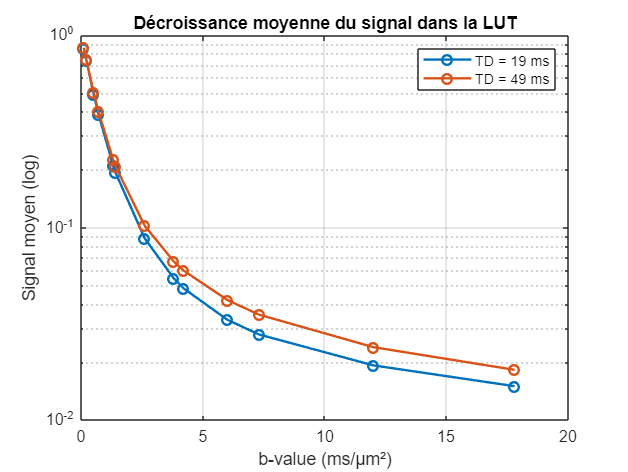

bvals = sequence.bval;
TDs   = sequence.TD;

% Moyenne sur toutes les simulations et directions
sig_mean = squeeze(mean(mean(signals_4D, 4), 1));  % [n_del × n_bval]

figure('Name', 'Décroissance signal moyen LUT');
colors = lines(sequence.n_del);
for d = 1:sequence.n_del
    semilogy(bvals, sig_mean(d,:), '-o', 'Color', colors(d,:), ...
        'DisplayName', sprintf('TD = %d ms', TDs(d)), 'LineWidth', 1.5);
    hold on;
end
xlabel('b-value (ms/µm²)');
ylabel('Signal moyen (log)');
title('Décroissance moyenne du signal dans la LUT');
legend('Location', 'northeast');
grid on;

% Vérifier visuellement : courbe lisse, décroissante, pas de saut aux b=4.2 et b=6.0

%% 7. Vérification de la isotropie directionnelle
% Pour chaque (simulation, TD, bval), std/mean sur les directions doit être faible
sig_dir_std  = std(signals_4D, 0, 4);   % [Ncombos × n_del × n_bval]
sig_dir_mean = mean(signals_4D, 4);

cv = sig_dir_std ./ (sig_dir_mean + 1e-10);  % coefficient de variation
fprintf('\n=== Isotropie directionnelle ===\n');


=== Isotropie directionnelle ===


fprintf('CV moyen sur directions : %.4f\n', mean(cv(:)));

CV moyen sur directions : 0.1793


fprintf('CV max sur directions   : %.4f\n', max(cv(:)));

CV max sur directions   : 2.5318


% Un CV > 0.3 sur des signaux moyennés sur 64 directions serait suspect

%% 8. Vérification de la couverture des paramètres
fprintf('\n=== Couverture des paramètres ===\n');


=== Couverture des paramètres ===


param_names = {'f', 'Dex', 'rmean', 'rsd'};
for p = 1:4
    fprintf('%s : min=%.3f | max=%.3f | mean=%.3f\n', ...
        param_names{p}, min(params(:,p)), max(params(:,p)), mean(params(:,p)));
end

f : min=0.001 | max=0.997 | mean=0.471
Dex : min=1.000 | max=3.000 | mean=1.996
rmean : min=1.000 | max=20.000 | mean=10.508
rsd : min=0.000 | max=5.000 | mean=2.331


% Vérifier que les ranges correspondent bien aux bornes Sobol définies

disp('=== Vérification terminée ===');

=== Vérification terminée ===


# Sanity check

% Sanity check sur sphere_0001
paravalues = readmatrix(fullfile(projectpath, 'sphere_0001', 'sim_para.txt'));
NPar = paravalues(3);
sig = readmatrix(fullfile(projectpath, 'sphere_0001', 'sig_diffusion.txt'));
sig_norm = sig / NPar;

fprintf('Après normalisation :\n');

Après normalisation :


fprintf('Min : %.6f\n', min(sig_norm));  % attendu ~0.2 (hauts b-values)

Min : 0.071607


fprintf('Max : %.6f\n', max(sig_norm));  % attendu ~0.875 (b=0.1)

Max : 0.877254


fprintf('Premier bloc (b=0.1, 3 directions) : %.4f | %.4f | %.4f\n', sig_norm(1), sig_norm(2), sig_norm(3));

Premier bloc (b=0.1, 3 directions) : 0.8755 | 0.8752 | 0.8755
